% Given Data
P1 = 50; % Chamber pressure in Pascals
P2 = 0; % Exit pressure (assumed to be 0 Pascals)
d = 0.8e-3; % Diameter of capillary tube in meters
L = 0.1; % Length of capillary tube in meters

% Time measurements (t2 in seconds)
t2 = [6, 10, 20, 30, 40]; % in seconds

% Calculate the plasma viscosity (mu) for each t2
mu = (P1 * d^2 .* t2) / (32 * L^2);

% Display the calculated plasma viscosity
fprintf('t2 (s)\t\tViscosity (mPa.s)\n');

t2 (s)		Viscosity (mPa.s)


for i = 1:length(t2)
    fprintf('%d\t\t%.4f\n', t2(i), mu(i) * 1000); % converting Pa.s to mPa.s
end

6		0.6000
10		1.0000
20		2.0000
30		3.0000
40		4.0000


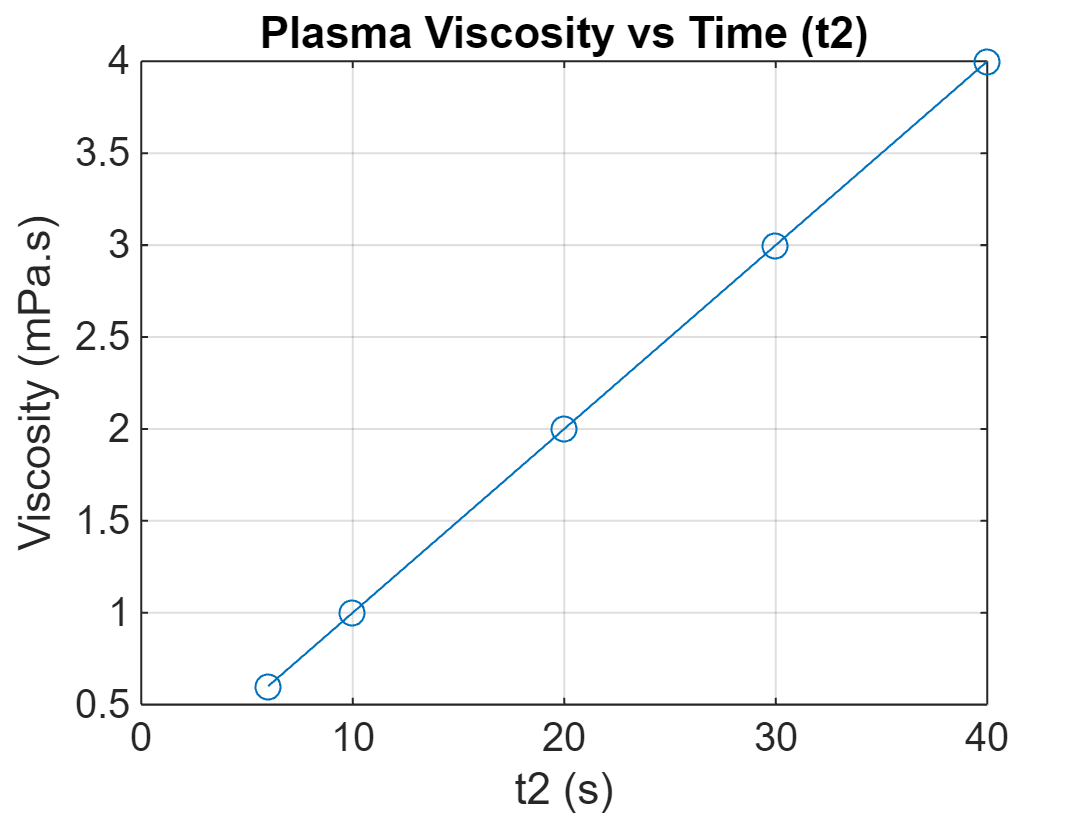


% Plotting viscosity as a function of t2
figure;
plot(t2, mu * 1000, '-o'); % converting Pa.s to mPa.s
xlabel('t2 (s)');
ylabel('Viscosity (mPa.s)');
title('Plasma Viscosity vs Time (t2)');
grid on;


% Estimating the total volume of plasma
V_total = pi * (d/2)^2 * L; % in cubic meters
V_total_cc = V_total * 1e6; % converting cubic meters to cubic centimeters
fprintf('Estimated total volume of plasma = %.4f cc\n', V_total_cc);

Estimated total volume of plasma = 0.0503 cc
